# Sleep Staging

## Path information

This first section is simply creating the paths to the EEG data and loading in the data. Please change the path, if necessary. Please enter the subject and run information in the format shown below.

Example: 

subjectID = osceeg17b;

run = run01;

subjectID = 'osceeg17b';

run = 'run01';

mainpath = ['/Volumes/Research/eng_research_lewislab/data/osceeg_frommgh/',subjectID];
channelpath = [mainpath,'/eeg/fs200_averef_regbcg/',run,'/c'];
hdrpath = [mainpath,'/eeg/fs200_averef_regbcg/',run,'/hdr'];
ecgpath = [mainpath,'/eeg/fs200_averef_regbcg/',run,'/ecg'];
resppath = [mainpath,'/eeg/fs200_averef_regbcg/',run,'/resp'];

% Loop to check which channel to go to for spec
occchan = occ_chan_per_subj(subjectID);
load([channelpath,num2str(occchan)]);
EEGspec = ch;
eegtitle = ['EEG Channel', num2str(occchan)];

% Load EEG/ECG data
channel = sleep_scor_chan(subjectID);
for i = 1:length(channel)
    load([channelpath,num2str(channel{i,2})])
    channel{i,3} = ch;
end


load(ecgpath);
ECG = ch;

load(hdrpath);
timeEEG = hdr.ts;


 


## Specgram & Click Times Plotting

This section plots the click times and the spectrogram on the same figure to assist in sleep staging. 

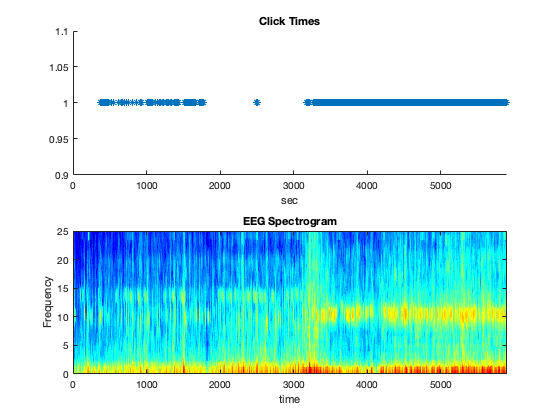

%% Click times, plotting
figure()
ax1 = subplot(2,1,1);
plotclicktimes(subjectID,run)


%% EEG spectrogram of run
dt = timeEEG(2)-timeEEG(1);
params=struct;
params.tapers=[10 19]; % [TW K] TK= time-bandwidth = sampling frequency*spectral width, K = 2*TW - 1
params.Fs=1/dt; % Set sampling rate here
params.fpass=[0 25]; % Set frequency range here
movingwin=[10 2]; % [windowlength windowslide]
[spec, t, f] = mtspecgramc_detrend_laura(EEGspec,movingwin,params);

%% Plotting specgram details

% figure();
ax2 = subplot(2,1,2);
imagesc(timeEEG,f,log10(spec')) %10*log10(S2)'
set(gca,'YDir','normal')
colormap('jet')
xlabel('time')
ylabel('Frequency')
title('EEG Spectrogram')

axisSpec = ax2.XLim;
linkaxes([ax2,ax1],'x');

ax2.XLim=axisSpec;

## Sleep Staging

In this section, first entire in a time interval to segment the data into. Push 'Enter' and then use the slider to go through the intervals of the eeg data and assign a value of sleep, drowsy, or wake. Please click save, to save the assigned sleep stage in the table.

% Zoom in
window = 90;
remain = rem(max(timeEEG),window);
int_t = 0:window:max(timeEEG);
int_t(length(int_t)+1)=remain+max(int_t);
Time = zeros(length(int_t)-1,2);
for i = 1:length(int_t)-1
    Time(i,1) = int_t(i);
    Time(i,2) = int_t(i+1);
end

Stage = cell(length(Time),1);
Index = 1:length(Time);
Index = Index';


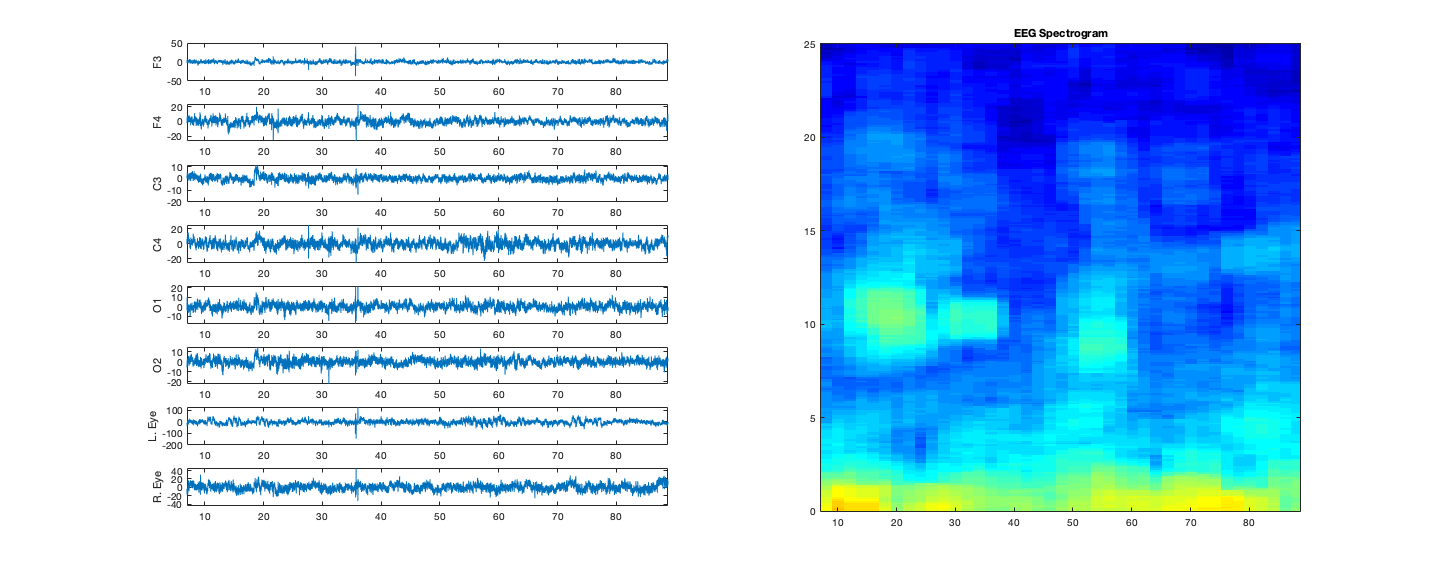

% Plots specgram for sleep staging (OPTION1)
figure();
set(gcf,'position',[20 50 2000 800])
axspec = subplot(8,2,2:2:16);
imagesc(timeEEG,f,log10(spec'))
set(gca,'YDir','normal')
colormap('jet')
%xlabel('time')
%ylabel('Frequency')
title('EEG Spectrogram')

ax = cell(1,length(channel));
j = 1;
for i = 1:length(channel)
   ax{i} = subplot(8,2,j);
   plot(timeEEG,channel{i,3})
   ylabel(channel{i,1}) 
   j = j+2;
end

linkaxes([ax{:},axspec],'x');



time_interval = 1;




xlim([Time(time_interval,1) Time(time_interval,2)]);

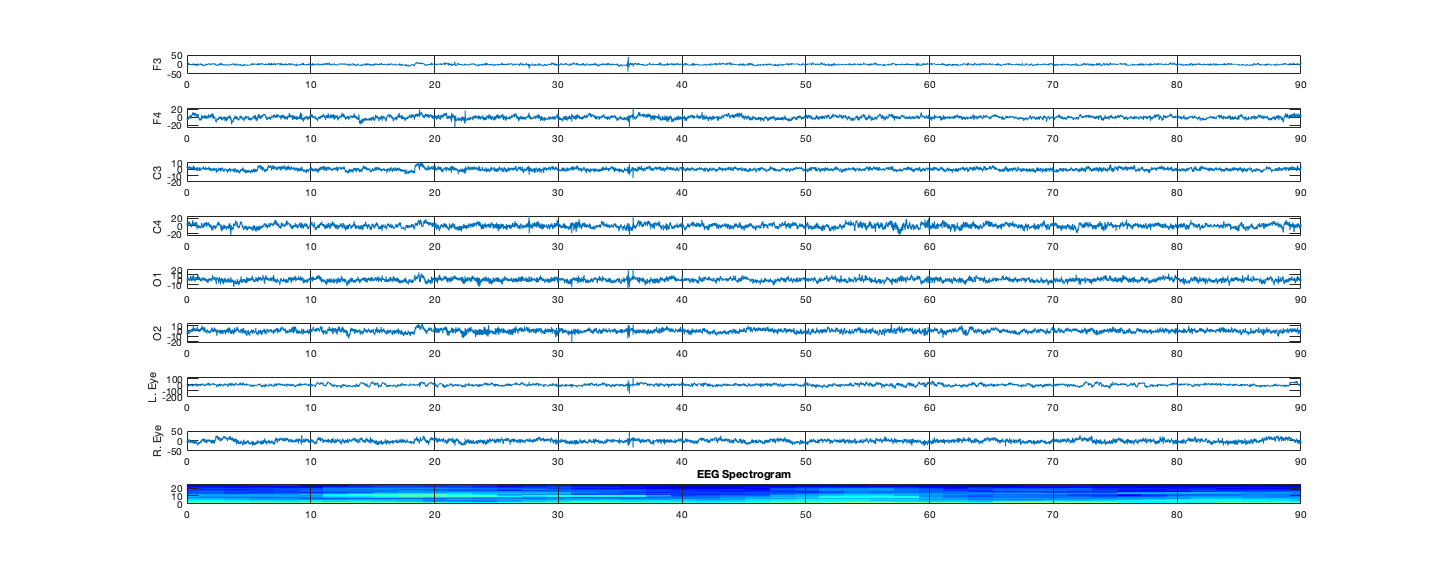

% Plots spec (OPTION2)
figure();
set(gcf,'position',[20 50 1500 600])
axspec = subplot(9,1,9);
imagesc(timeEEG,f,log10(spec'))
set(gca,'YDir','normal')
colormap('jet')
%xlabel('time')
%ylabel('Frequency')
title('EEG Spectrogram')

for i = 1:length(channel)
   ax{i} = subplot(9,1,i);
   plot(timeEEG,channel{i,3})
   ylabel(channel{i,1}) 
end

linkaxes([ax{:},axspec],'x');



time_interval = 1;




xlim([Time(time_interval,1) Time(time_interval,2)]);

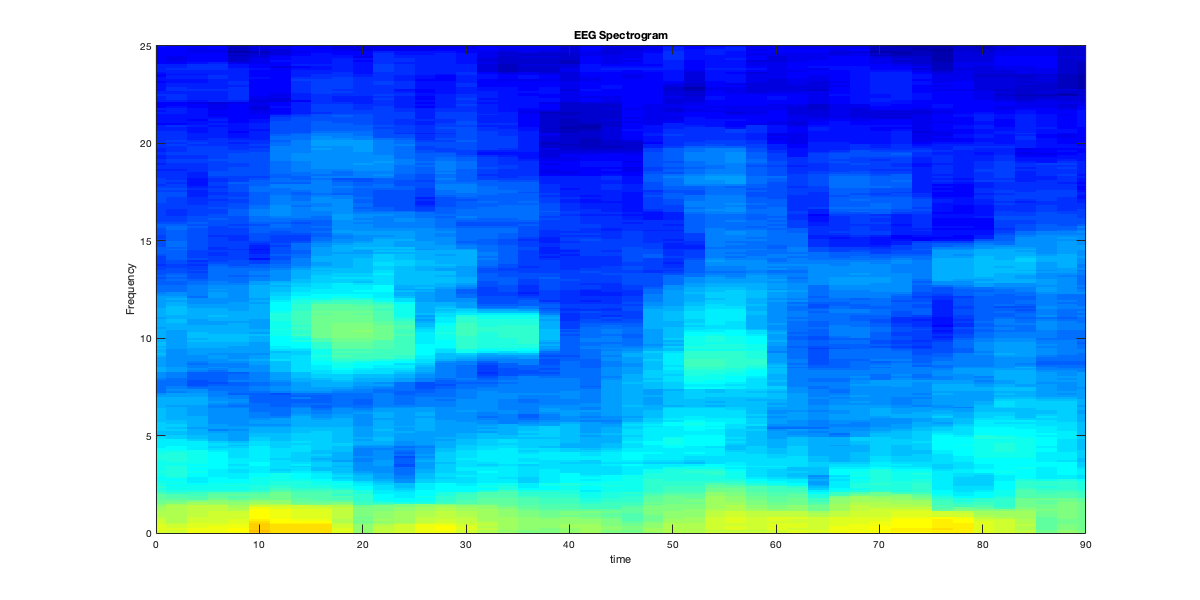

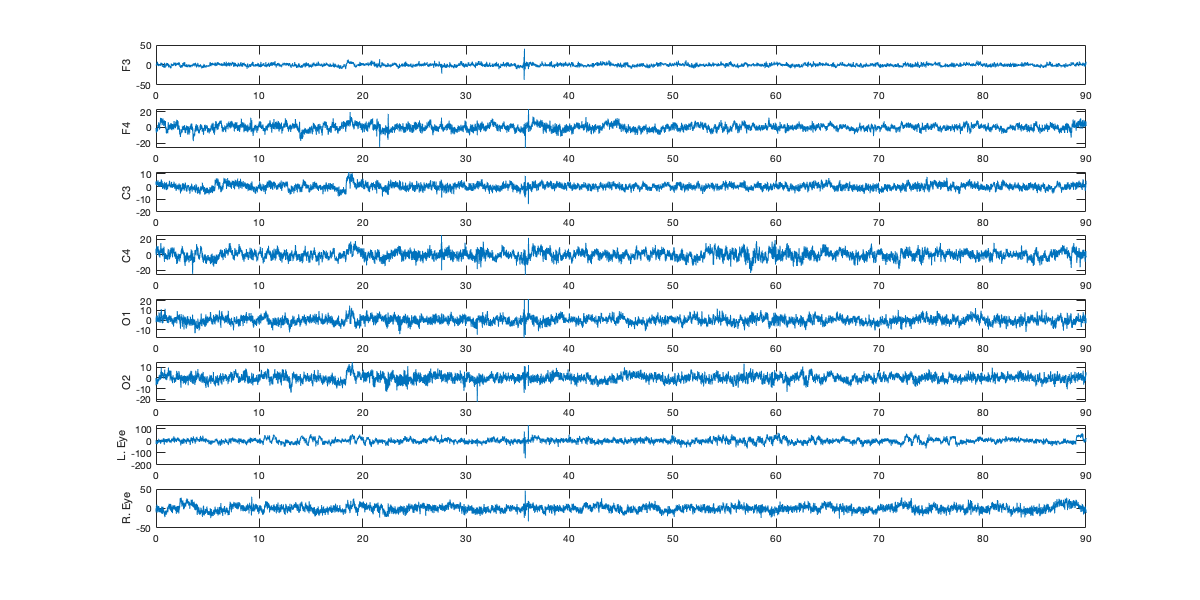

% Plots spec (OPTION3)
figure();
set(gcf,'position',[20 50 1200 600])
axspec = subplot(1,1,1);
imagesc(timeEEG,f,log10(spec'))
set(gca,'YDir','normal')
colormap('jet')
xlabel('time')
ylabel('Frequency')
title('EEG Spectrogram')

figure()
set(gcf,'position',[650 50 1200 600])
for i = 1:length(channel)
   ax{i} = subplot(8,1,i);
   plot(timeEEG,channel{i,3})
   ylabel(channel{i,1}) 
end

linkaxes([ax{:},axspec],'x');

time_interval = 1;




xlim([Time(time_interval,1) Time(time_interval,2)]);

% Plots the stages along the x axis
% bar graph style or plot with thick line width? 
% or add row in image




% Save sleep staging
Stage{time_interval} = 'Wake';
sleep_info = table(Index,Time,Stage);
disp(sleep_info)


 

## Save data

To save the data as a text file, please push 'save' to do so.

% Saves the data as a text file
fid = fopen('sleep_stages.txt','w');
if fid == -1
    fprintf('An error occured and a file could not be created.\n Please try again.\n')
else 
    fprintf(fid,'Time (sec)       Stage\n');
    for i = 1: length(Time)
        fprintf(fid,'[%6.1f %6.1f]  %s\n',Time(i,1),Time(i,2),Stage{i});
    end

end

stat = fclose(fid);
if stat == 0
    fprintf('The file has been successfully saved as: sleep_stages.txt');
else 
    fprintf('An error occurred. The file may not hae saved correctly.')
end

 